# **IO17x - Temperature Sensor Measurement**

The IO171 and IO172 I/O modules offer versatile support to measure ungrounded thermocouples, resistive sensors such as resistance temperature detectors (RTD) and thermistors, and strain gauges.

This example shows you how to read the temperature from two different sensors with either the IO171 or the IO172. The Simulink model features the [IO17x Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io17x_setup) and the [IO17x Analog Input](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io17x_analog_input) block.

## Setup

### Prerequisites

You will require the following to run this example:

- Speedgoat real-time target machine with one IO171 or one IO172 I/O module installed

- Connector cable from the I/O module to the terminal board

- IO171 or IO172 terminal board with an onboard thermal sensor

- Type J thermocouple sensor

- Type PT 1000 RTD sensor

### Test Setup

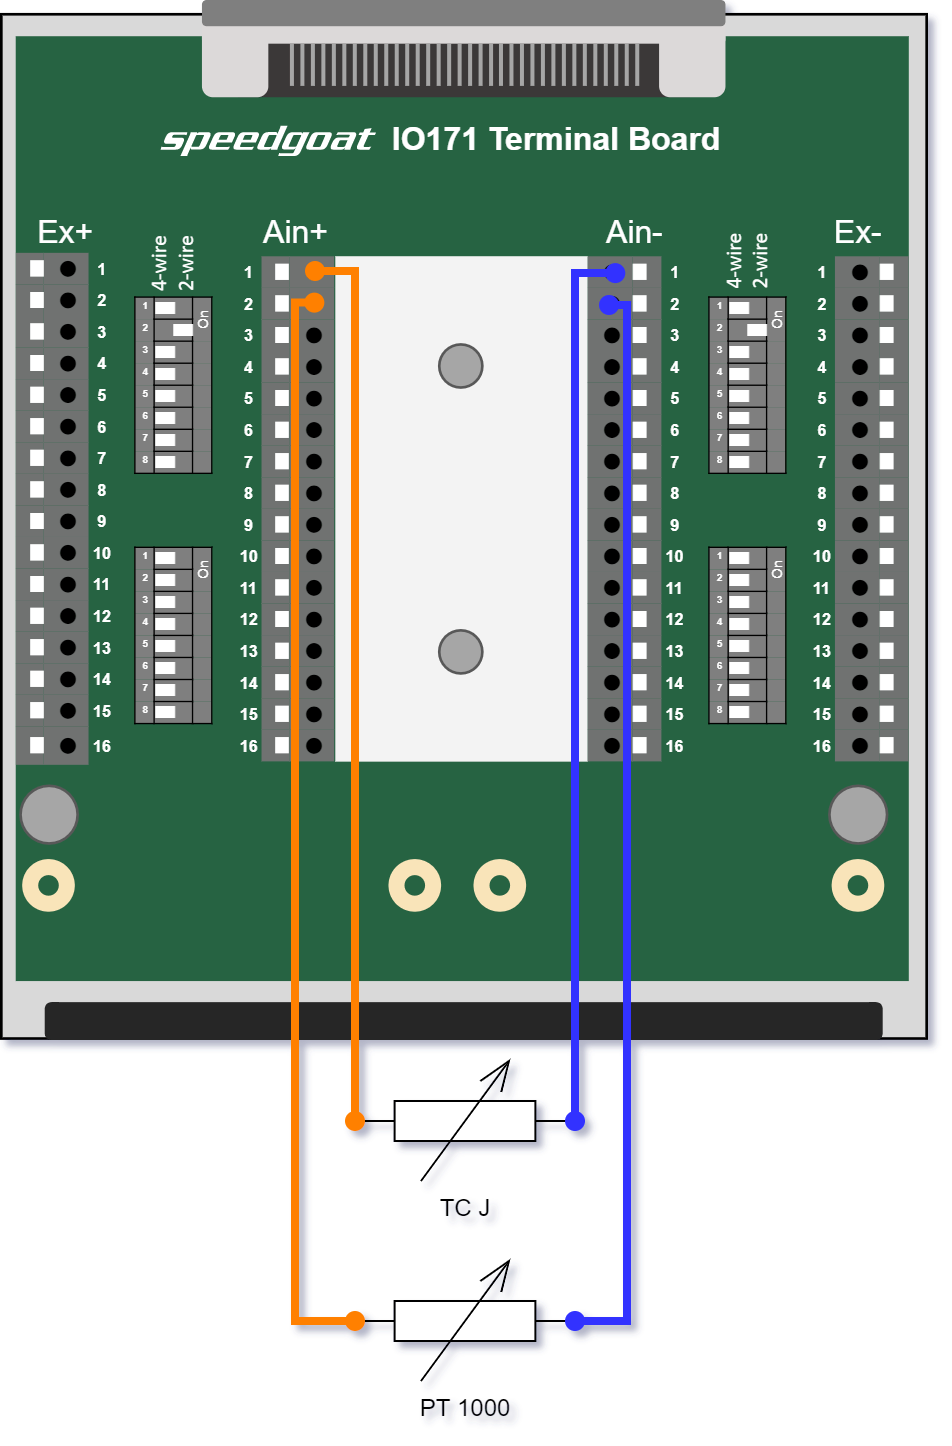↖ IO171 Terminal Board

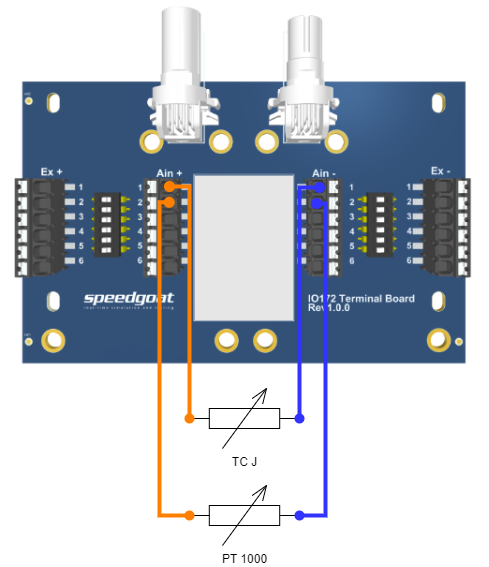↖ IO172 Terminal Board

In this example, either the IO171 or the IO172 terminal board is used, which includes the cold junction compensation for thermocouples. The cold junction compensation is achieved by an isothermal block which thermally connects all 32 / 12 sensor terminals (Ain+ and Ain-). The IO171 / IO172 automatically measures the temperature of the aluminum block using an SE95 thermal sensor.

As thermocouples do not require any external excitation, the switches for channel 1 must be set to OFF (2-wire) and the sensor must be connected to the dedicated analog input pins. The RTD sensors require an excitation, which can be connected to the sensor using the 2- or 4-wire mode. If the sensor has only two wires use the 2-wire mode, otherwise use the 4-wire mode and connect it to the dedicated analog input and excitation pins of channel 2. Please refer to the [IO171 Pin Mapping](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io171_pin_mapping) or [IO172 Pin Mapping](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io172_pin_mapping), and [IO17x Terminal Boxes](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io17x_terminal_box) for the location of the correct pins.

## Initialize and Open the Simulink model

 
% Open Simulink model
modelName = 'sgMdl_IO17x_Temperature';
open_system(modelName);

### Select the Module Type

Select either IO171 or IO172, depending on which I/O module you are using. When the dropdown value is changed, the blocks in the Simulink model are configured for the new module type.

moduleType = 'IO171';
set_param([modelName, '/Setup '], 'parModuleType', moduleType);
set_param([modelName, '/Analog input '], 'parModuleType', moduleType);

### Model Description

In the model, the  [IO17x Analog Input](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io17x_analog_input) block reads the temperature and displays it in a scope. In the [IO17x Setup block](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io17x_setup), channel 1 is configured to use a type J thermocouple sensor as well as the external sensor from the IO17x terminal board for the cold junction compensation. A type PT 1000 RTD sensor is configured for channel 2. The sample time is set to 100 ms which is above the time needed for a conversion. Both sensors, the thermocouple and the RTD, have a conversion time of 22 ms. For other sensor types refer to the [IO17x Usage Notes](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io17x_usage_notes).

The status and error outputs allow you to check if a conversion has completed and no error has occurred. This information is provided for each enabled channel resulting in a vector output. The sensor temperature output stays at the old value in case of an error.

## Build, Download, and Run the Example

To run the example, either run the following code section or click the **Run on Target** button in the **REAL-TIME** tab in the Simulink model.

 
% Build the Simulink model
slbuild(modelName); % this will create the real-time application file (.mldatx)

% Create and connect to the Speedgoat real-time target machine
tg = slrealtime;
tg.connect;

% Download and install the real-time application on the target machine
tg.load(modelName);

% Connect the Simulink model with external mode to the real-time application on the target machine
set_param(modelName, 'SimulationMode', 'external') % put model into External Mode
set_param(modelName, 'SimulationCommand', 'connect') % connect with External Mode
% set_param(modelName,'SimulationCommand','start')      % start real-time application through Simulink toolstrip

% Start the real-time application
tg.start;

% Wait a few seconds and then stop the real-time application on the target machine
pause(10)
tg.stop;

### Check the Results

To check the temperature output, open the first Simulink scope connected to the [IO17x Analog Input](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io17x_analog_input) block. In the first scope, three temperature signals must be displayed, reflecting the current temperature of the connected sensors and the temperature from the external sensor of the IO17x terminal board. The second scope shows the status and error outputs for each enabled channel. The status must have a value of one and the error must have a value of zero.

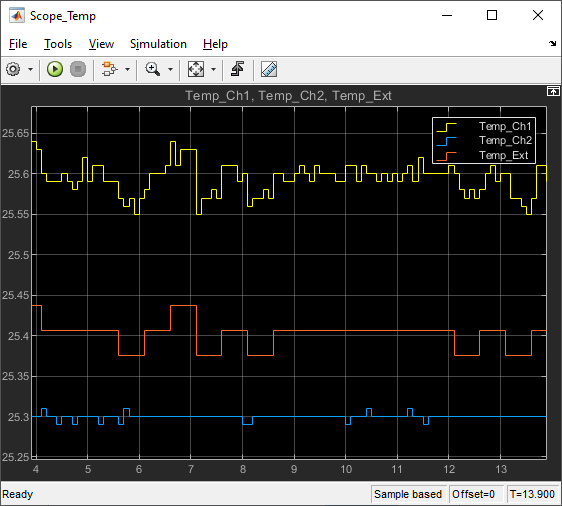   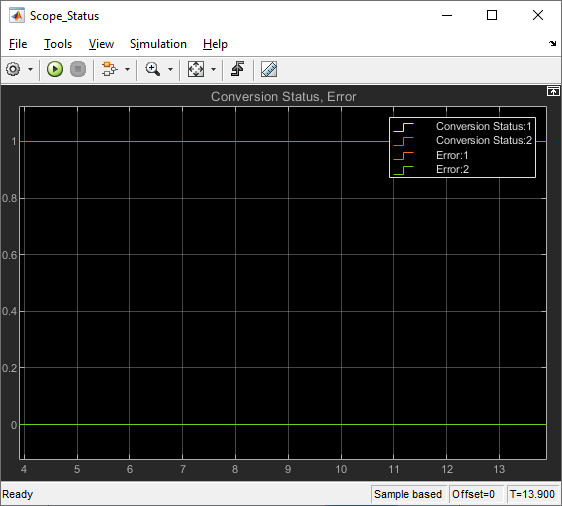

## Additional References

- [IO17x documentation and examples](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_io17x)